## Self-positioning using aircraft signals and reference sensors

Okay, let's start doing the real heavy lifting since Python couldn't handle some few millions of lines

% Load data
clear; clc;
% Helper functions' path
addpath('geodesy');

% Note that for training we have results as well
training = false;

if training
    DIRECTORY_NUM = '5';
    MEASUREMENTS_DIR = sprintf('../datasets/round_1/%g/training_%g_category_1', DIRECTORY_NUM, DIRECTORY_NUM);
    RESULTS_DIR = sprintf('../datasets/round_1/%g/training_%g_category_1_result', DIRECTORY_NUM, DIRECTORY_NUM);

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = sprintf('training_%g_category_1.csv', DIRECTORY_NUM);
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = 'training_{}_category_1_result.csv';
else
    MEASUREMENTS_DIR = '../datasets/round_1';
    RESULTS_DIR = '';

    % We have 2 sets: measurements and results (to compare our approach to)
    MEASUREMENTS_CSV = 'round1_competition.csv';
    SENSORS_CSV = 'sensors.csv';
    RESULTS_CSV = '';
end

CACHE = 'workspace.mat';

Start the parallel pool (to speed up some computations)

if isempty(gcp('nocreate'))
    parpool('local', 4, 'IdleTimeout', 120);
end

Load data (first check if it's in the cache, otherwise it's gonna take long)

if isfile(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE))
    load(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
else
    f = true;
    [aircraft, sensors] = loadData(MEASUREMENTS_DIR, MEASUREMENTS_CSV, SENSORS_CSV, f);
    ddoa = getddoa(aircraft);
    save(sprintf('%s/%s', MEASUREMENTS_DIR, CACHE), 'ddoa', 'aircraft', 'sensors');
end

% Speed of light is 299792458 m/s
c = 299792458;
ddoa.ddoam = ddoa.ddoa * 1e-9 * c;

backup_sensors = sensors; backup_aircraft = aircraft; backup_ddoa = ddoa;

% User this to restore everything
sensors = backup_sensors;
aircraft = backup_aircraft;
ddoa = backup_ddoa;

fraction = 4;
aircraft = aircraft(aircraft.id <= max(ddoa.id)/fraction,:);
ddoa = ddoa(ddoa.id <= max(ddoa.id)/fraction,:);

## Computing cartesian distances

% Computing cartesian coordinates
xyz = llh2ecef([aircraft.latitude, aircraft.longitude, aircraft.geoAltitude]);
aircraft.x = xyz(:,1);
aircraft.y = xyz(:,2);
aircraft.z = xyz(:,3);

% Let's obtain the coordinates of the aircraft measurements and also relate them
% with the average positon
center = [(quantile(aircraft.x,0.01) + quantile(aircraft.x,0.99))/2, ...
          (quantile(aircraft.y,0.01) + quantile(aircraft.y,0.99))/2, ...
          (quantile(aircraft.z,0.01) + quantile(aircraft.z,0.99))/2];
      
aircraft.x = aircraft.x - center(1);
aircraft.y = aircraft.y - center(2);
aircraft.z = aircraft.z - center(3);

% For reproducible results
rng('default');

latlims = [max(sensors.latitude), min(sensors.latitude)];
lonlims = [max(sensors.longitude), min(sensors.longitude)];

% Let's shuffle the sensors

% Let's only keep sensors that appear on the measurements
keep = zeros(size(sensors,1),1) == 1;
for ii = 1:size(sensors,1)
    if any(ddoa.s1 == sensors.serial(ii)) || any(ddoa.s2 == sensors.serial(ii))
        keep(ii) = true;
    end
end

sensors_shuffled = sensors(keep,:);
% masklat = sensors_shuffled.latitude > quantile(sensors_shuffled.latitude,0.1) & sensors_shuffled.latitude < quantile(sensors_shuffled.latitude, 0.9);
% masklon = sensors_shuffled.longitude > quantile(sensors_shuffled.longitude,0.1) & sensors_shuffled.longitude < quantile(sensors_shuffled.longitude, 0.9);
% sensors_shuffled = sensors_shuffled(masklat & masklon, :);

% Let's also compute the cartesian coordinates
xyz = llh2ecef([sensors_shuffled.latitude, sensors_shuffled.longitude, sensors_shuffled.height]);
sensors_shuffled.x = xyz(:,1) - center(1);
sensors_shuffled.y = xyz(:,2) - center(2);
sensors_shuffled.z = xyz(:,3) - center(3);

% We can compute the errors between the measured and expected TDOAs
maskddoa = ismember(ddoa.s1, sensors_shuffled.serial, 'rows') & ismember(ddoa.s2, sensors_shuffled.serial, 'rows');
ddoa = ddoa(maskddoa,:);

[~,acId] = ismember(ddoa.id, aircraft.id, 'rows');
[~,s1Id] = ismember(ddoa.s1, sensors_shuffled.serial, 'rows');
[~,s2Id] = ismember(ddoa.s2, sensors_shuffled.serial, 'rows');

acd = table2array(aircraft(acId,{'x', 'y', 'z'}));
s1d = table2array(sensors_shuffled(s1Id,{'x', 'y', 'z'}));
s2d = table2array(sensors_shuffled(s2Id,{'x', 'y', 'z'}));

% Computation of TDOAs
d1 = ecef_distance(acd, s1d);
d2 = ecef_distance(acd, s2d);

exp = d1 - d2;
ddoa.exp = exp;
ddoa.err = exp - ddoa.ddoam;

## Inspecting sensors

[pids, pairs] = findgroups(ddoa(:,{'s1','s2'}));
pairs.rmedn = splitapply(@(x) sqrt(median((x - median(x)).^2)), abs(ddoa.err), pids);
pairs.rmean = splitapply(@(x) sqrt(mean(x - median(x)).^2), abs(ddoa.err), pids);
pairs.std = splitapply(@std, ddoa.err, pids);
pairs.n = splitapply(@length,ddoa.err, pids);

scatter(pairs.rmedn, pairs.std, 25, pairs.n, 'filled');
colorbar;
xlabel('Root Median Squared Error (m)');
ylabel('Standard Deviation (m)');

scatter(pairs.rmean, pairs.std, 25, pairs.n, 'filled');
colorbar;
xlabel('Root Mean Squared Error (m)');
ylabel('Standard Deviation (m)');

mask = pairs.n > 500 & pairs.rmean < 100 & pairs.std < 200;
scatter(pairs.rmedn(mask), pairs.std(mask), 25, pairs.n(mask), 'filled');
colorbar;
xlabel('Root Median Squared Error (m)');
ylabel('Standard Deviation (m)');

## Removing outliers

Some of the measurements are completely off and break the optimization.

Light travels almost 300.000 km per second.

A TDOA error of 30.000 km is not really possible (it's almost the earth circumference) so those measurements should be broken

maskerr = ddoa.err > quantile(ddoa.err,0.01) & ddoa.err < quantile(ddoa.err,0.99);
ddoa = ddoa(maskerr,:);

% We can obtain the ids of the sensors that are 'good'
% good = unique([pairs.s1(mask); pairs.s2(mask)]);
% sensors_shuffled = sensors_shuffled(ismember(sensors_shuffled.serial,good),:);
% ddoa = ddoa(ismember(ddoa.s1,good) & ismember(ddoa.s2,good),:);

## Optimization

In this part, now that we have loaded everything, let's make some optimizations and see the results

% Initial value initialization
tmp = zeros(height(sensors_shuffled),1);
xyz0 = table(tmp, tmp, tmp, 'VariableNames',{'x', 'y', 'z'});

% Let's set up a fraction of sensors that are reference
fraction = 0.3;
R = round(height(sensors_shuffled)*fraction);

for ii = 1:R
    xyz0.x(ii) = sensors_shuffled.x(ii);
    xyz0.y(ii) = sensors_shuffled.y(ii);
    xyz0.z(ii) = sensors_shuffled.z(ii);
end

for ii = R+1:height(sensors_shuffled)
    s = sensors_shuffled.serial(ii);
    mask = (ddoa.s1 == s) | (ddoa.s2 == s);
    unique_id = unique(ddoa.id(mask));
    [~,idx,~] = intersect(aircraft.id,unique_id);
    
    xyz0.x(ii) = mean(aircraft.x(idx));
    xyz0.y(ii) = mean(aircraft.y(idx));
    xyz0.z(ii) = mean(aircraft.z(idx));
end

% Let's see the initial errors
p0 = [sensors_shuffled.x, sensors_shuffled.y, sensors_shuffled.z];
p1 = [xyz0.x, xyz0.y, xyz0.z];

histogram(ecef_distance(p0, p1)/1e3);
xlabel('Error (km)');
ylabel('Number of Sensors');

## First optimization attempt

% For the optimization, we will use fmincon:
% https://ch.mathworks.com/help/optim/ug/fmincon.html
% It allows for constraints and memory usage is minimal since it needs the
% squared sum of the error not the residuals

% The general form is: fmincon(fun,x0,A,b,Aeq,beq,lb,ub)
N = height(sensors_shuffled);
fun = @(x) minimizer(x(0*N+1:1*N), x(1*N+1:2*N), x(2*N+1:3*N), sensors_shuffled.serial, aircraft, ddoa);

% Lower & Upper bounds
lbx = [sensors_shuffled.x(1:R); -inf*ones(height(sensors_shuffled)-R,1)];
lby = [sensors_shuffled.y(1:R); -inf*ones(height(sensors_shuffled)-R,1)];
lbz = [sensors_shuffled.z(1:R); -inf*ones(height(sensors_shuffled)-R,1)];
lb = [lbx;lby;lbz];

ubx = [sensors_shuffled.x(1:R); inf*ones(height(sensors_shuffled)-R,1)];
uby = [sensors_shuffled.y(1:R); inf*ones(height(sensors_shuffled)-R,1)];
ubz = [sensors_shuffled.z(1:R); inf*ones(height(sensors_shuffled)-R,1)];
ub = [ubx;uby;ubz];

% Some options for the algorithm
options = optimoptions('fmincon','Display','iter-detailed','Algorithm','interior-point',...
                       'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                       'OptimalityTolerance',1e-12,'FunctionTolerance',1e-12,'StepTolerance',1e-12);
%                        'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-15);
                   
% Here starts the fun
x0 = [xyz0.x; xyz0.y; xyz0.z];
tic;
[res, fval, flag, output, lambda] = fmincon(fun,x0,[],[],[],[],lb,ub,[],options);
toc;

% Test function speed
tic;
[res, grad] = minimizer(sensors_shuffled.x, sensors_shuffled.y, sensors_shuffled.z, sensors_shuffled.serial, aircraft, ddoa);
toc;

% Evaluating the rms
positions = reshape(res,[],3);
unknown = positions(R+1:end,:);
realpos = table2array(sensors_shuffled(R+1:end,{'x','y','z'}));

errors = unknown - realpos;
errnrm = sqrt(sum(errors.^2,2));

rmse = rms(errnrm)

% Let's calculate the 3D error
quant = 1
errnrm85 = errnrm(errnrm < quantile(errnrm,quant)); % Let's see where a percentage of the values lie
ecdf(errnrm85); grid on;
xlabel('Error (m)');
title(sprintf('3D Error ECDF (%d%% quantile)',quant*100));

% Compute the 2D distance
unknownllh = ecef2llh(unknown + center);
realposllh = table2array(sensors_shuffled(R+1:end, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh);
rms(dist)
ecdf(dist); grid on;
xlabel('Error (m)');
title('2D Error ECDF');

## Another optimization approach

Okay we played with optimizing all sensors and setting some constraints to the known sensors

That is likely inefficient, since ground sensor residuals need to be computed even though there is no possibility to change them

Thus, let's focus on the problem for each sensor where only one of the operands is known

% For the optimization, we will use fmincon:
% https://ch.mathworks.com/help/optim/ug/fmincon.html
% It allows for constraints and memory usage is minimal since it needs the
% squared sum of the error not the residuals
ground = sensors_shuffled(1:R,:);
N = height(sensors_shuffled);

result = zeros(N-R,3);
for ii = R+1:N
    serial = sensors_shuffled.serial(ii);
    fun = @(x) minimizer2(x(1), x(2), x(3), serial, aircraft, ddoa, ground(:,{'x','y','z','serial'}));
    
    % Some options for the algorithm
    options = optimoptions('fminunc','Display','none','Algorithm','quasi-newton',...
                           'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                           'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-12);
                       
    % Here starts the fun
    x0 = [xyz0.x(ii); xyz0.y(ii); xyz0.z(ii)];
    tic;
    [position,fval,flag] = fminunc(fun,x0,options);
    toc;
    if fval ~= 0
        result(ii-R,:) = position;
    else
        result(ii-R,:) = [0.0 0.0 0.0];
    end
end

tic;
[res,grad] = minimizer2(sensors_shuffled.x(R+1),sensors_shuffled.y(R+1),sensors_shuffled.z(R+1),sensors_shuffled.serial(R+1),aircraft,ddoa,ground(:,{'x','y','z','serial'}));
toc;

% Let's calculate errors
unknownsens = sensors_shuffled(R+1:end,:);
valid = find(~all(result==0,2));
resval = result(valid,:); senval = table2array(unknownsens(valid,{'x','y','z'}));

errors = resval - senval;
errnrm = sqrt(sum(errors.^2,2));

rmse = rms(errnrm)

rmse = 7.5578e+03

% Compute the 2D distance
unknownllh = ecef2llh(resval + center);
realposllh = table2array(sensors_shuffled(R+1:end, {'latitude','longitude','height'}));
realposllh = realposllh(valid,:);

dist = havdist(unknownllh, realposllh);
rmse_2d = sqrt(median(dist.^2))

rmse_2d = 42.8560

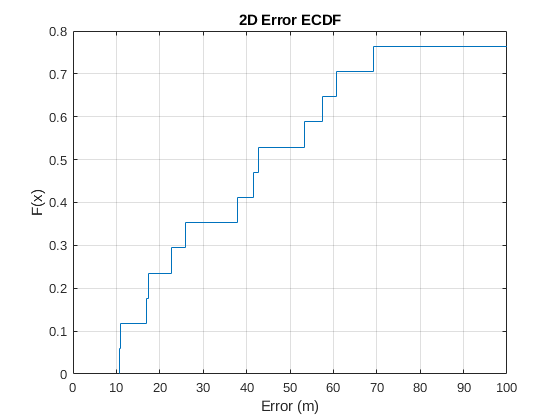

ecdf(dist); grid on;
xlabel('Error (m)');
title('2D Error ECDF');
xlim([0,100]);

## Yet another optimization approach

It seems errors are improved, but what if we can add some offset to our measurements?

% For the optimization, we will use fmincon:
% https://ch.mathworks.com/help/optim/ug/fmincon.html
% It allows for constraints and memory usage is minimal since it needs the
% squared sum of the error not the residuals
ground = sensors_shuffled(1:R,:);

% Let's do some Linear Least squares to estimate the offsets of the ground
% sensors
mask_g = ismember(ddoa.s1,ground.serial) & ismember(ddoa.s2,ground.serial);
ddoa_ground = ddoa(mask_g,:);

% Linear least squares solves problems of the type:
% min ||Cx - d||^2
% with A*x < b
% lb < x < ub
% In our case d is -ddoa.err and C is the matrix with (1, -1) in the positions
% of (s1, s2) respectively

% We start with the C matrix
C = zeros(height(ddoa_ground), height(ground));
for index = 1:height(ground)
    s = ground.serial(index);
    mask_positive = ddoa_ground.s1 == s;
    mask_negative = ddoa_ground.s2 == s;
    
    C(mask_positive, index) = 1;
    C(mask_negative, index) = -1;
end

% Now the d vector
d = -ddoa_ground.err;

% We set the lower and upper bounds
sigma = std(ddoa_ground.err);
lb = [-1e-6; -5*sigma.*ones(height(ground)-1,1)];
ub = [1e-6; 5*sigma.*ones(height(ground)-1,1)];

offsets = lsqlin(C,d,[],[],[],[],lb,ub);


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


ground.offsets = offsets;

% Now that we have the offsets let's start with the real optimization
N = height(sensors_shuffled);
result = zeros(N-R,4);
for ii = R+1:N
    serial = sensors_shuffled.serial(ii);
    fun = @(x) minimizeroffset(x(1), x(2), x(3), x(4), serial, aircraft, ddoa, ground(:,{'x','y','z','offsets','serial'}));
    
    % Some options for the algorithm
    options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton',...
                           'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                           'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-12, 'OptimalityTolerance',1e-12);
                       
    % Here starts the fun
    x0 = [xyz0.x(ii); xyz0.y(ii); xyz0.z(ii); 2*5*sigma*rand(1)-5*sigma];
    tic;
    [position,fval,flag] = fminunc(fun,x0,options);
    toc;
    if fval ~= 0
        result(ii-R,:) = position;
    else
        result(ii-R,:) = [0.0 0.0 0.0 0.0];
    end
end

Elapsed time is 10.821477 seconds.
Elapsed time is 6.622039 seconds.
Elapsed time is 7.000240 seconds.
Elapsed time is 6.875026 seconds.
Elapsed time is 8.978263 seconds.
Elapsed time is 6.289720 seconds.
Elapsed time is 7.218156 seconds.
Elapsed time is 6.370738 seconds.
Elapsed time is 13.891356 seconds.
Elapsed time is 9.600882 seconds.
Elapsed time is 6.566918 seconds.
Elapsed time is 6.440865 seconds.
Elapsed time is 28.408503 seconds.
Elapsed time is 8.858389 seconds.
Elapsed time is 7.581663 seconds.
Elapsed time is 8.407570 seconds.
Elapsed time is 7.157736 seconds.


% Let's calculate errors
unknownsens = sensors_shuffled(R+1:end,:);
valid = find(~all(result==0,2));
invalid = find(all(result==0,2));
resval = result(valid,:); senval = table2array(unknownsens(valid,{'x','y','z'}));

errors = resval(:,1:3) - senval;
errnrm = sqrt(sum(errors.^2,2));

rmse = sqrt(median(errnrm.^2))

rmse = 194.8083

% Compute the 2D distance
unknownllh = ecef2llh(resval(:,1:3) + center);
realposllh = table2array(sensors_shuffled(R+1:end, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh(valid,:));
rmse_2d = sqrt(median(dist.^2))

rmse_2d = 53.0625

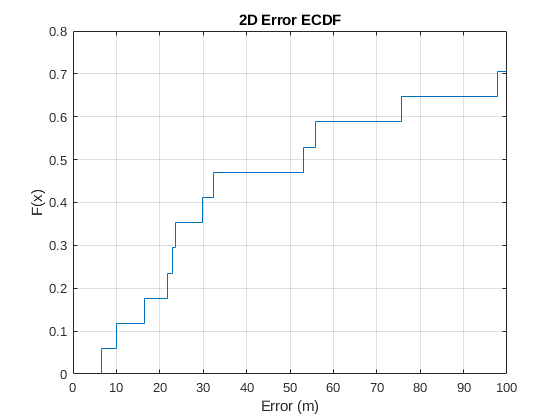

figure();
ecdf(dist); grid on;
xlabel('Error (m)');
title('2D Error ECDF');
xlim([0,100]);

## More Optimization approaches

In this one, we will use all sensors but one and optimize the position (imitating a user)

result = zeros(height(sensors_shuffled),4); % x, y, z & offset

for ii = 1:height(sensors_shuffled)
    %% Data preparation
    sensor = sensors_shuffled(ii,:);
    
    gId = 1:height(sensors_shuffled); gId(ii) = [];
    ground = sensors_shuffled(gId,:);
    % Let's do some Linear Least squares to estimate the offsets of the ground
    % sensors
    mask_g = ismember(ddoa.s1,ground.serial) & ismember(ddoa.s2,ground.serial);
    ddoa_ground = ddoa(mask_g,:);

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Linear least squares    
    % We start with the C matrix
    C = zeros(height(ddoa_ground), height(ground));
    for index = 1:height(ground)
        s = ground.serial(index);
        mask_positive = ddoa_ground.s1 == s;
        mask_negative = ddoa_ground.s2 == s;
        
        C(mask_positive, index) = 1;
        C(mask_negative, index) = -1;
    end
    
    % Now the d vector
    d = -ddoa_ground.err;
    
    % We set the lower and upper bounds
    sigma = std(ddoa_ground.err);
    lb = [-1e-6; -5*sigma.*ones(height(ground)-1,1)];
    ub = [1e-6; 5*sigma.*ones(height(ground)-1,1)];
    
    offsets = lsqlin(C,d,[],[],[],[],lb,ub);
    ground.offsets = offsets;
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    %% Computing initial point
    mask = (ddoa.s1 == sensor.serial) | (ddoa.s2 == sensor.serial);
    unique_id = unique(ddoa.id(mask));
    [~,idx,~] = intersect(aircraft.id,unique_id);
    
    p0.x = mean(aircraft.x(idx));
    p0.y = mean(aircraft.y(idx));
    p0.z = mean(aircraft.z(idx));
    
    %% Now that we have the offsets let's start with the real optimization
    fun = @(x) minimizeroffset(x(1), x(2), x(3), x(4), sensor.serial, aircraft, ddoa, ground(:,{'x','y','z','offsets','serial'}));
    
    % Some options for the algorithm
    options = optimoptions('fminunc','Display','off','Algorithm','quasi-newton',...
                           'SpecifyObjectiveGradient',true,'UseParallel',true,'MaxIterations',1000,...
                           'MaxFunctionEvaluations', 300000, 'StepTolerance',1e-12, 'OptimalityTolerance',1e-12);
                       
    % Here starts the fun
    x0 = [p0.x; p0.y; p0.z; 2*5*sigma*rand(1)-5*sigma];
    tic;
    [position,fval,flag] = fminunc(fun,x0,options);
    toc;
    if fval ~= 0
        result(ii,:) = position';
    else
        result(ii,:) = [0.0 0.0 0.0 0.0];
    end
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 11.268662 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.653561 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 14.851990 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 11.679544 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 11.108980 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 14.571275 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.714201 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 13.011668 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 10.744411 seconds.



Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



Elapsed time is 14.693705 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 8.939166 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 10.332708 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.487344 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.730559 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 11.844231 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 13.285766 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 10.691625 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 18.257583 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 32.171270 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 11.730302 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.785161 seconds.



Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



Elapsed time is 10.000809 seconds.



Solver stopped prematurely.

lsqlin stopped because it exceeded the iteration limit,
options.MaxIterations = 2.000000e+02.



Elapsed time is 10.344150 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 10.723063 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 15.403472 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 15.459584 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 14.381319 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 14.270520 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 12.200984 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 15.033256 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 9.839045 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 16.889484 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 17.061150 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 16.055895 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 13.951153 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 16.420539 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 13.846183 seconds.



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


Elapsed time is 14.269693 seconds.


% Let's calculate errors
unknownsens = sensors_shuffled;
valid = find(~all(result==0,2));
invalid = find(all(result==0,2));
resval = result(valid,1:3); senval = table2array(unknownsens(valid,{'x','y','z'}));

errors = resval(:,1:3) - senval;
errnrm = sqrt(sum(errors.^2,2));

rmse = sqrt(median(errnrm.^2))

rmse = 98.7720

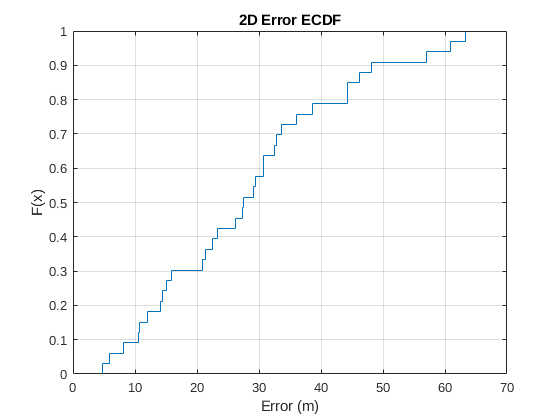

% Compute the 2D distance
unknownllh = ecef2llh(resval(:,1:3) + center);
realposllh = table2array(sensors_shuffled(:, {'latitude','longitude','height'}));

dist = havdist(unknownllh, realposllh(valid,:));
[distno,id] = rmoutliers(dist);
rmse_2d = rms(distno);
figure();
ecdf(distno); grid on;
xlabel('Error (m)');
title('2D Error ECDF');

## The Map (to visualize everything)

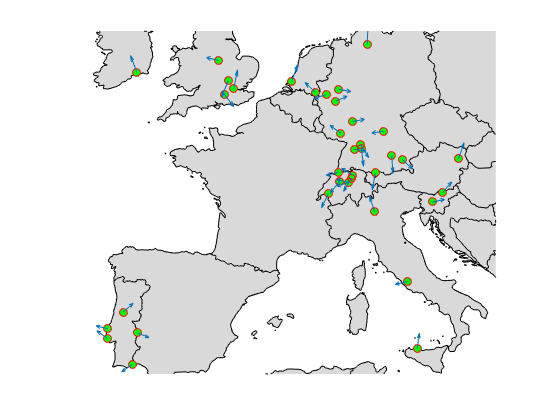

% prepare the map
figure
ax = worldmap([20 70],[-30 40]);
hold on
setm(ax, 'MapProjection',"mercator", 'Frame',"off", 'Grid',"off")
%% zoom in
ax.XLim = [-1.7846e+06 1.5681e+06];
ax.YLim = [4.3808e+06 7.1748e+06];
% plot borders / lands
geoshow(ax, 'shapefiles/CNTR_RG_10M_2016_4326.shp', 'FaceColor',[0.85 0.85 0.85]);
% plot ground station locations
scatterm(ground.latitude, ground.longitude, [], 'magenta', 'filled');
% plot sensor locations (green dots)
scatterm(realposllh(valid,1), realposllh(valid,2), [], 'green', 'filled');
% plot sensor locations (green dots)
scatterm(realposllh(invalid,1), realposllh(invalid,2), [], 'yellow', 'filled');
% plot result locations (red circles)
scatterm(unknownllh(:,1), unknownllh(:,2), [], 'red');
% calculate the directions
vec = [unknownllh(:,1) - realposllh(valid,1), unknownllh(:,2) - realposllh(valid,2)];
vec = vec ./ vecnorm(vec')';
quiverm(realposllh(valid,1), realposllh(valid,2), vec(:,1), vec(:,2), 0.2);
hold off